# ELEN 133L Lab 4 -- Ayden Dauenhauer and Alan Rieger

## Step 1

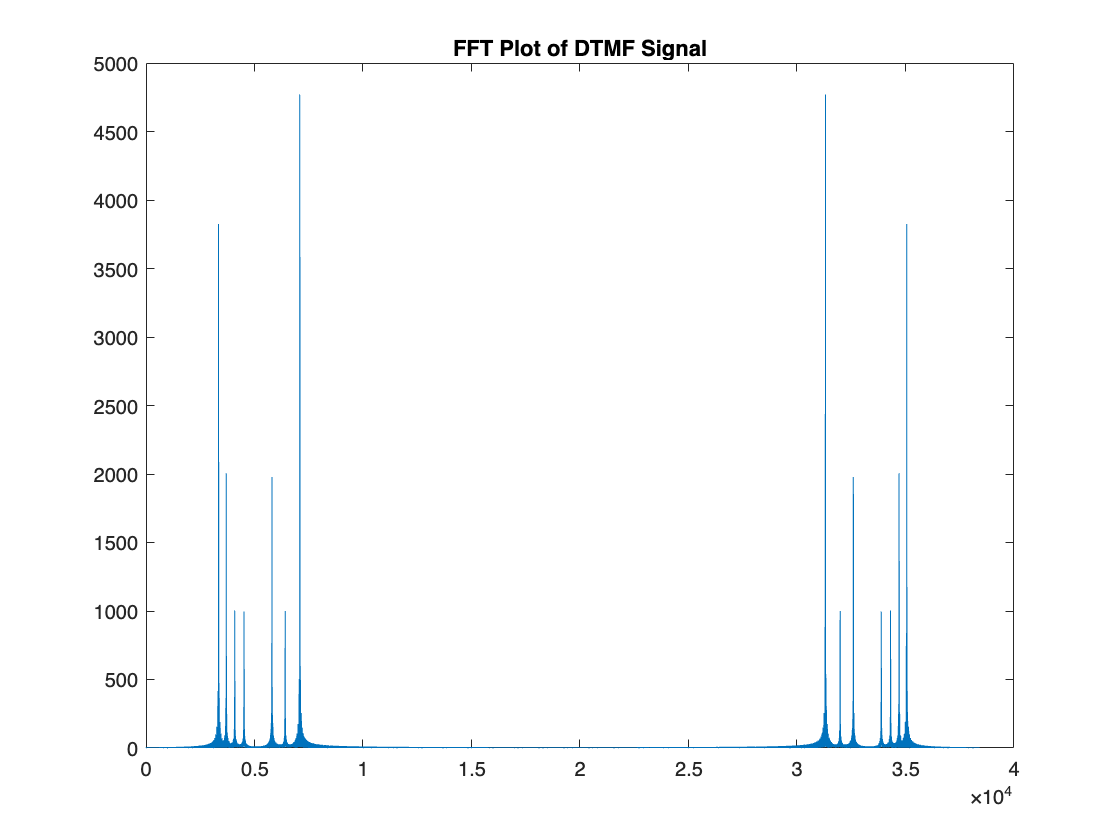

fs = 8000;
tone_len = 0.5;
quiet_len = 0.1;
tone_arr = [1, 2, 3, 3, 4, 6, 9, 12];
n = 8;
dt = 1/fs;

x = ELEN133L_Lab2(tone_len, quiet_len, fs, tone_arr);
time = n * (tone_len + quiet_len);
X=fft(x);
plot(abs(X))
title('FFT Plot of DTMF Signal')

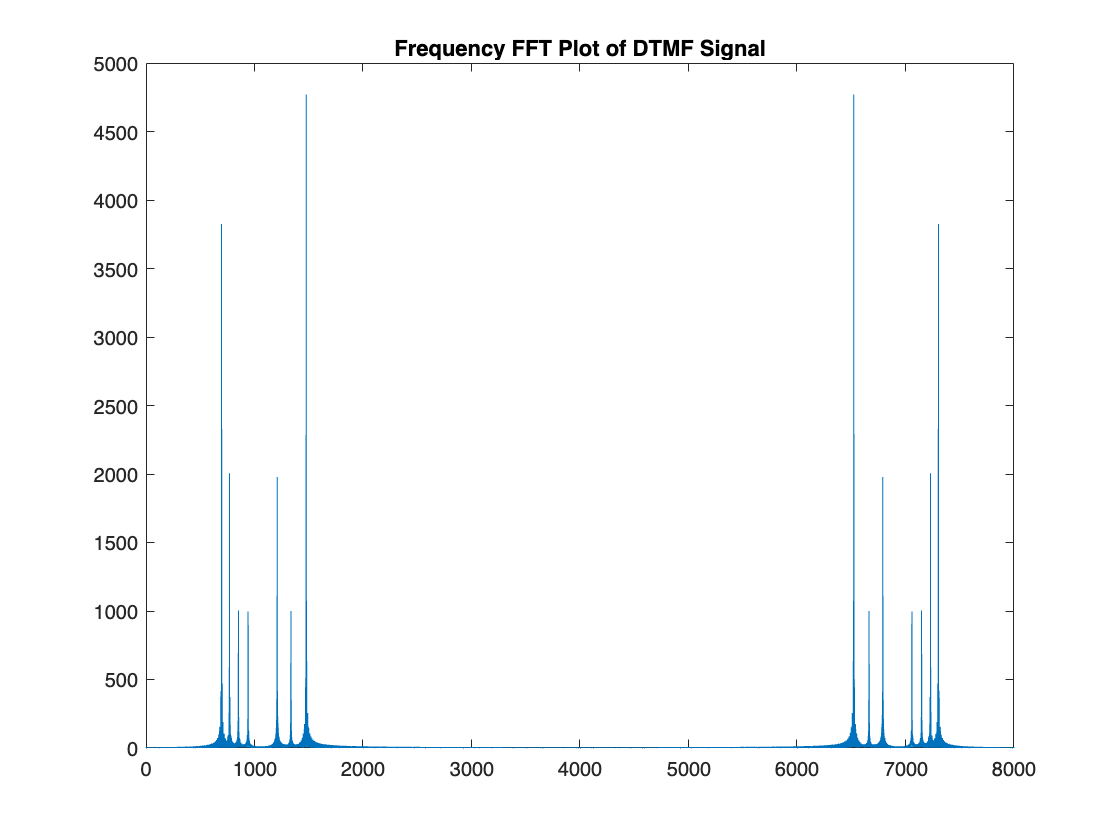

dF = fs/length(X);
fv = (0:length(X)-1)*dF;
plot(fv, abs(X));
title('Frequency FFT Plot of DTMF Signal')

**On this plot identify the horizontal location and height of the peak of each pulse on the left half of the display.**

**Record the height of each pulse as well as the center frequency and width in Hz of each pulse.**

    *From right to left

    First value: frequency, Second value: height

    datatip(chart,1477,4771);

    datatip(chart,1336,956.5);

    datatip(chart,1209,1977);

    datatip(chart,941,996.4);

    datatip(chart,852.1,1004);

    datatip(chart,770,2006);

    datatip(chart,696.7,3824);

**How would you characterize the shape of the pulses?**

    They are narrow spikes.

**Explain the amplitudes of the pulses on the left half of the plot in terms of the buttons specified in dialvals.**

    There are 7 peaks and 7 unique dial numbers. And they spike at the row and column frequencies for the DTMF.

**What are the pulses on the right half of the plot?**

    They are mirrored pulses of the left side of the plot. (fs - f)

**Can you tell what sequence of buttons generated this signal just by looking at this result? Why or why not?**

    No because there is no way of telling which was pressed first, just whether or not is was pressed.

     It just plots the row and column frequencies and not when they're used.

## Step 2

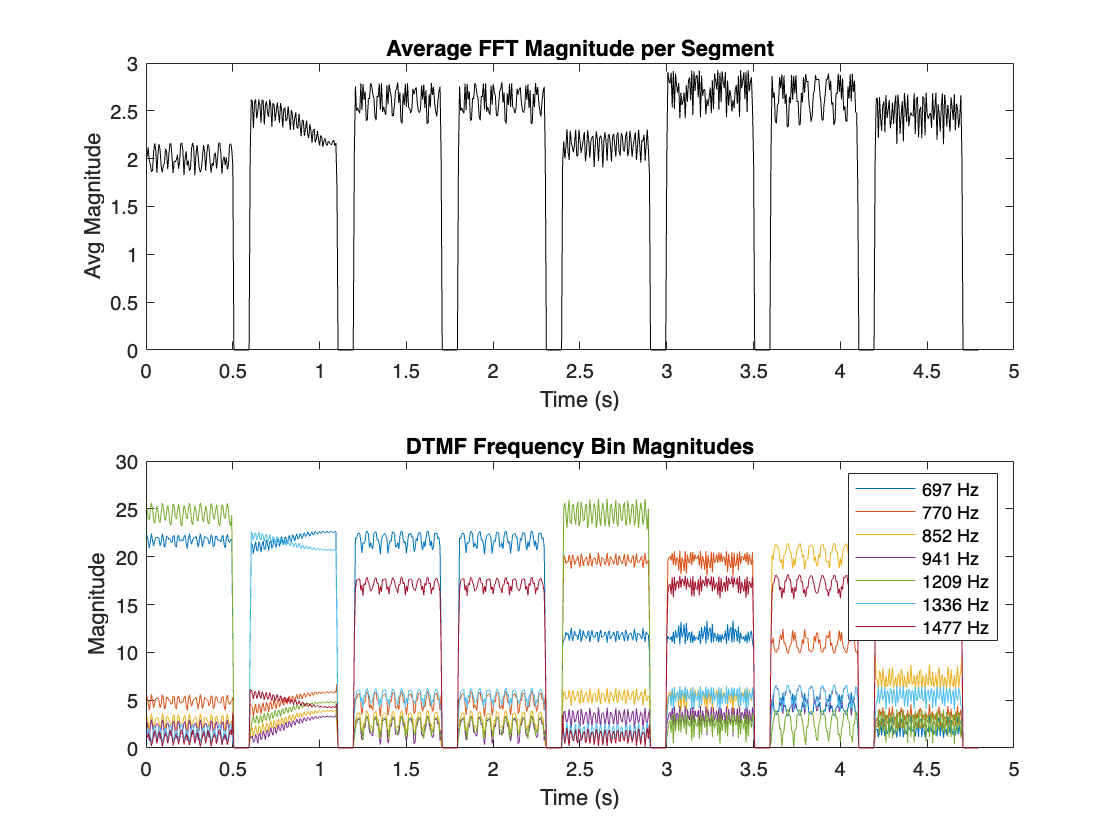

seg_width = 100;
ELEN133L_Lab4_2(x, seg_width);

**Does the average value clearly show the difference between when a button signal is present and when there is a quiet period?**

    Yes, there are gaps between each button press, which we can see on the plot.

**Do the row and column magnitude plots accurately show when these tones are present?**

    Yes, there are obvious row and column frequencies, corresponding to each button pressed, which have a higher average magnitude on the plot.

**What rule would you use to decide which button had been pressed at each time during the signal?**

    Compare the row and column frequencies with the highest average magnitudes for each button pressed. Each of the two highest average magnitudes for     

    each button pressed will be the row and column frequencies for that button press.

**Is there a chance for confusions or wrong detections?**

    Yes, there is a chance for wrong detections based on if there is noise or other irregularities that cause one of the frequencies to have a higher average 

    magnitude than the correct row and column frequency for that button.

## **Step 3**

**Compute the DFT frequencies represented by the seven frequency indices you selected in Step 1 and compare them to the desired tone frequencies. Which is closest? Which has the most difference?**

    Desired Frequency: 697    Actual Frequency: 720

    Desired Frequency: 770    Actual Frequency: 800

    Desired Frequency: 852    Actual Frequency: 880

    Desired Frequency: 941    Actual Frequency: 960

    Desired Frequency: 1209    Actual Frequency: 1200

    Desired Frequency: 1336    Actual Frequency: 1360

    Desired Frequency: 1477    Actual Frequency: 1440

    Closest is 1200 to 1209, which has a difference of 9

    Most different is 1477 to 1440, which has a difference of 37

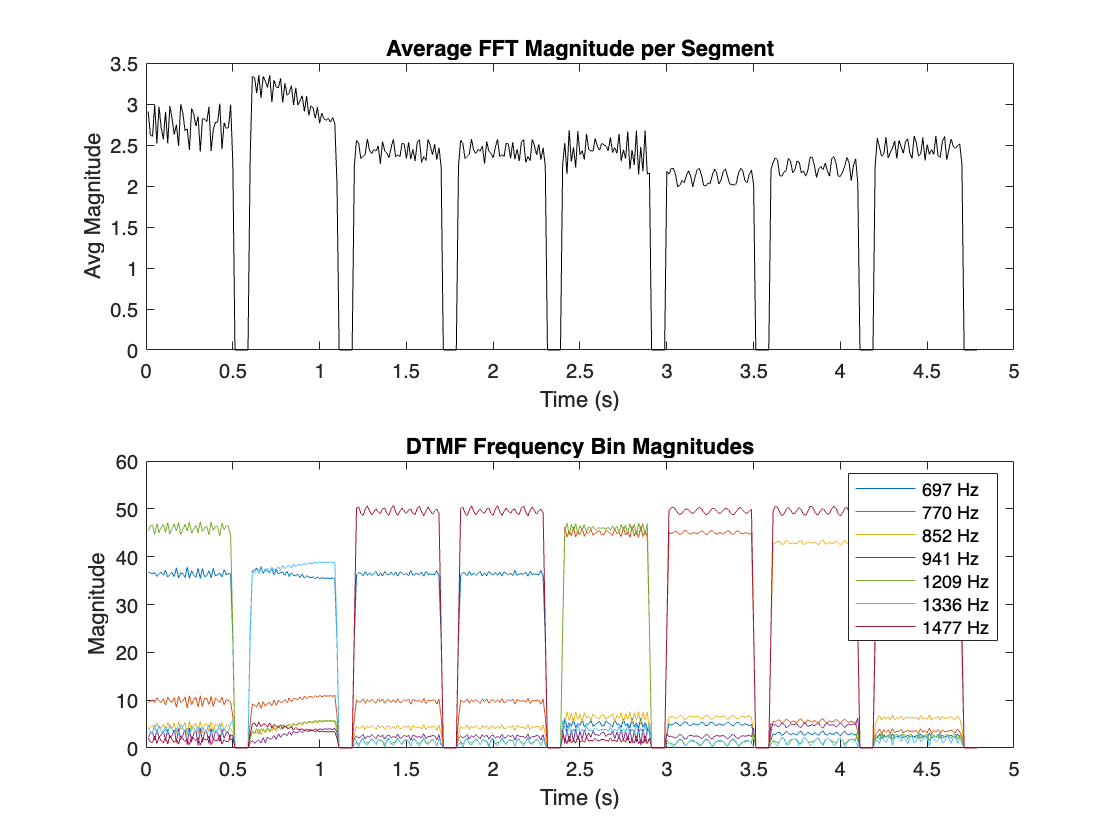

seg_width = 200;
ELEN133L_Lab4_2(x, seg_width);

**For each length, compute the DFT frequencies represented by the seven frequency indices you selected and compare them to the desired tone frequencies.**

    Desired Frequency: 697    Actual Frequency: 680

    Desired Frequency: 770    Actual Frequency: 760

    Desired Frequency: 852    Actual Frequency: 840

    Desired Frequency: 941    Actual Frequency: 960

    Desired Frequency: 1209    Actual Frequency: 1200

    Desired Frequency: 1336    Actual Frequency: 1320

    Desired Frequency: 1477    Actual Frequency: 1480

    Closest is 1477 to 1480, which has a difference of 3

    Most different is 941 to 960, which has a difference of 19

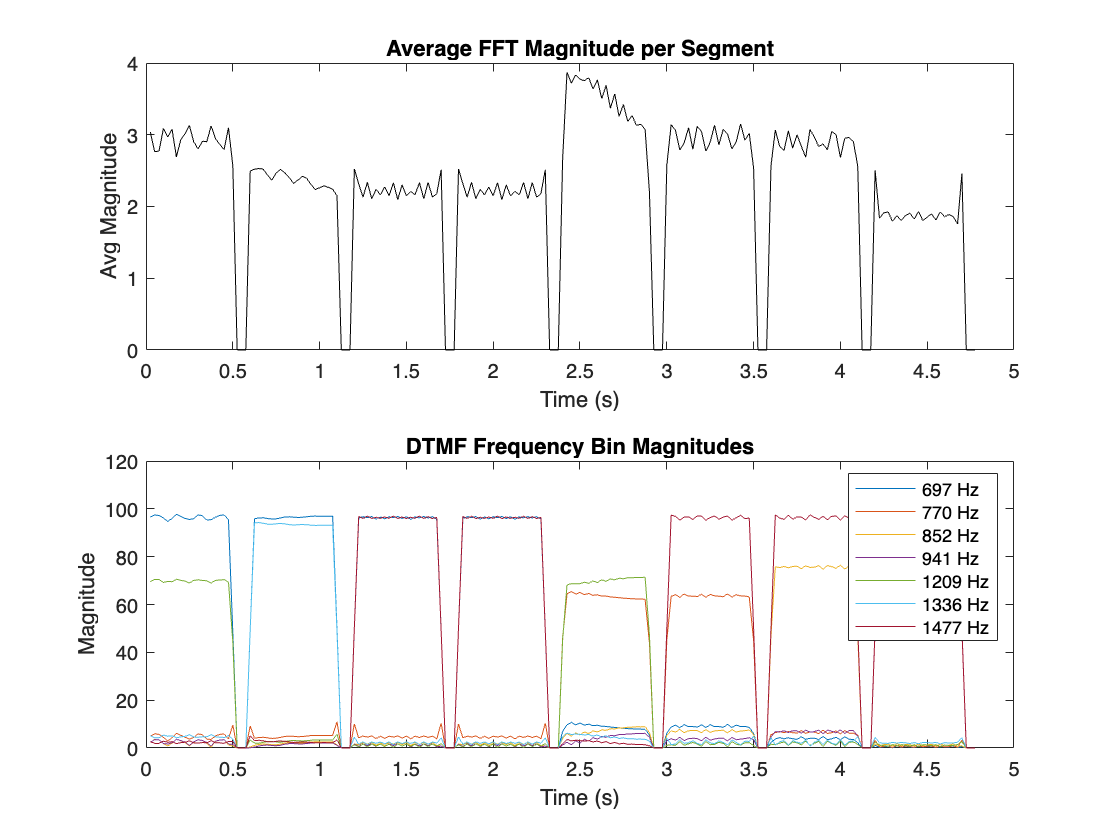

seg_width = 400;
ELEN133L_Lab4_2(x, seg_width);

**For each length, compute the DFT frequencies represented by the seven frequency indices you selected and compare them to the desired tone frequencies.**

    Desired Frequency: 697    Actual Frequency: 700

    Desired Frequency: 770    Actual Frequency: 760

    Desired Frequency: 852    Actual Frequency: 860

    Desired Frequency: 941    Actual Frequency: 940

    Desired Frequency: 1209    Actual Frequency: 1200

    Desired Frequency: 1336    Actual Frequency: 1340

    Desired Frequency: 1477    Actual Frequency: 1480

    Closest is 941 to 940, which has a difference of 1

    Most different is 1209 to 1200, which has a difference of 9

fs = 8000;
dtmf_freqs = [697 770 852 941 1209 1336 1477];

seg_widths = [100, 200, 400];

for w = seg_widths
    freqs = (0:w-1) * fs / w;
    for f = dtmf_freqs
        [~, idx] = min(abs(freqs - f));
        actual_freq = freqs(idx);
        error = abs(actual_freq - f);
    end
end

From this data, we can tell that as seg_width goes up the difference between the desired and actual frequencies goes down. 

## **Step 4**

## **2*segwidth Function Plots**

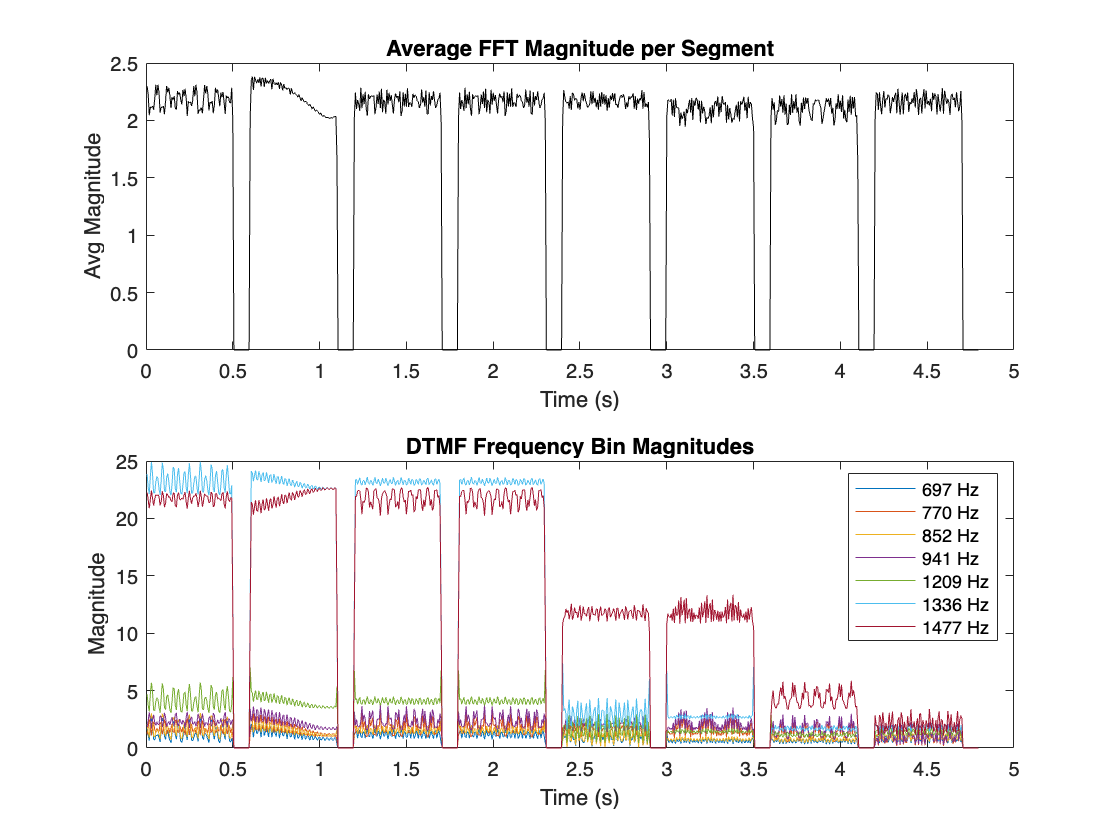

seg_width = 100;
ELEN133L_Lab4_3(x, seg_width);

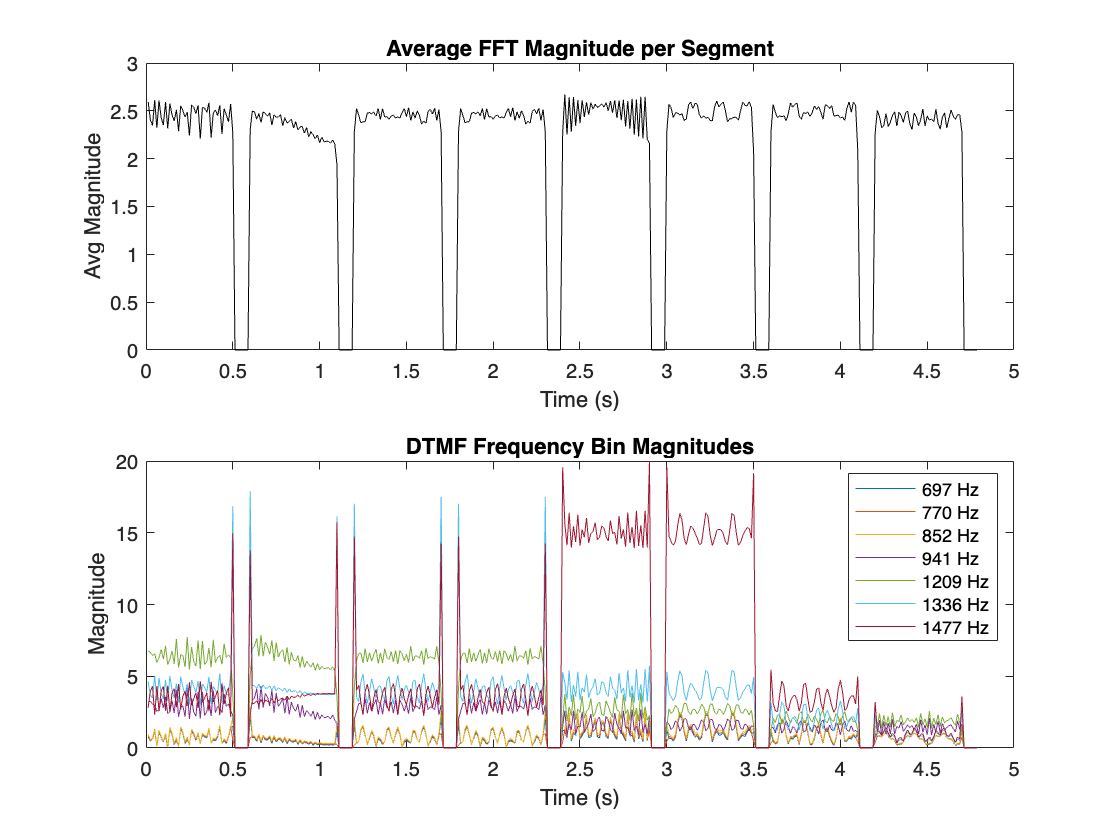

seg_width = 200;
ELEN133L_Lab4_3(x, seg_width);

**Compare these results with the original results for seg_width = 100.**

    The lower frequencies are still distinguishable but the higher frequencies gets harder to tell which button was pressed based on the row and column 

    frequencies. The average FFT magnitude plot still looks roughly the same.

**Compare these results with the original results for seg_width = 200.**

    The average FFT magnitude plot still looks roughly the same. The button presses are all indistinguishable based on the row and column frequencies in the     

    plot where as in the original plot, we could still distinguish them.

## **4*segwidth Function Plots**

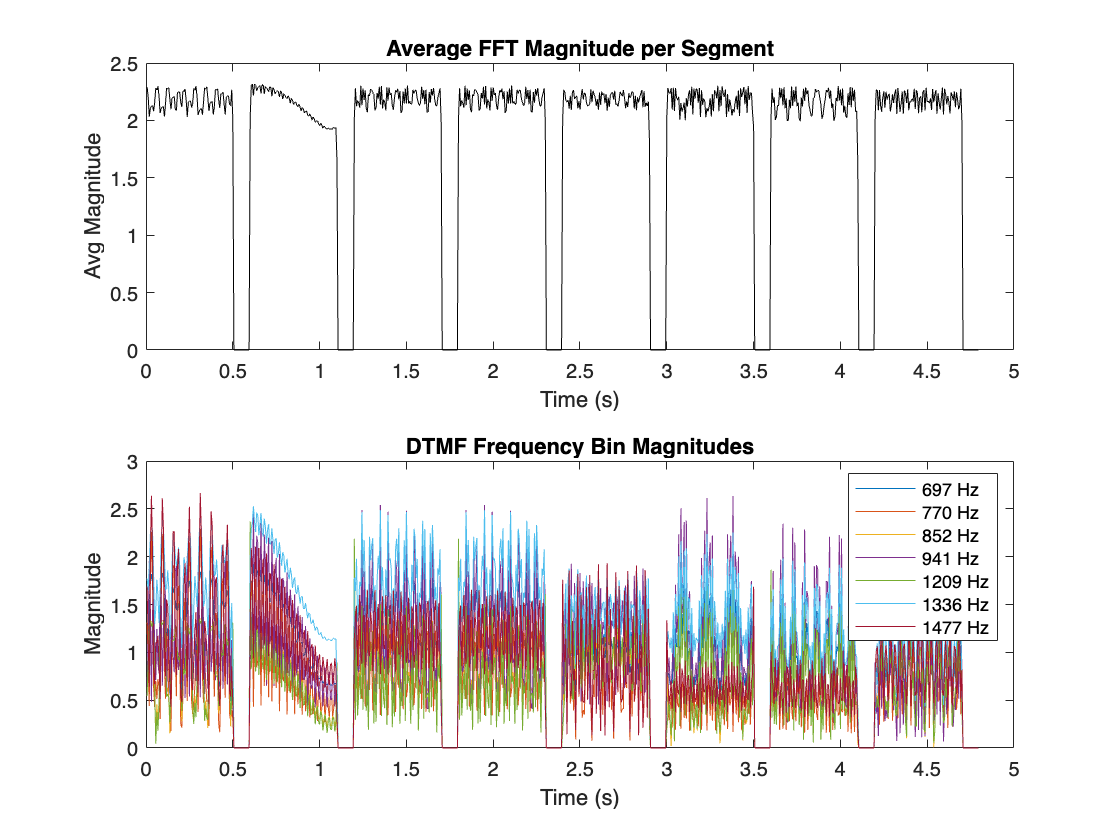

seg_width = 100;
ELEN133L_Lab4_4(x, seg_width);

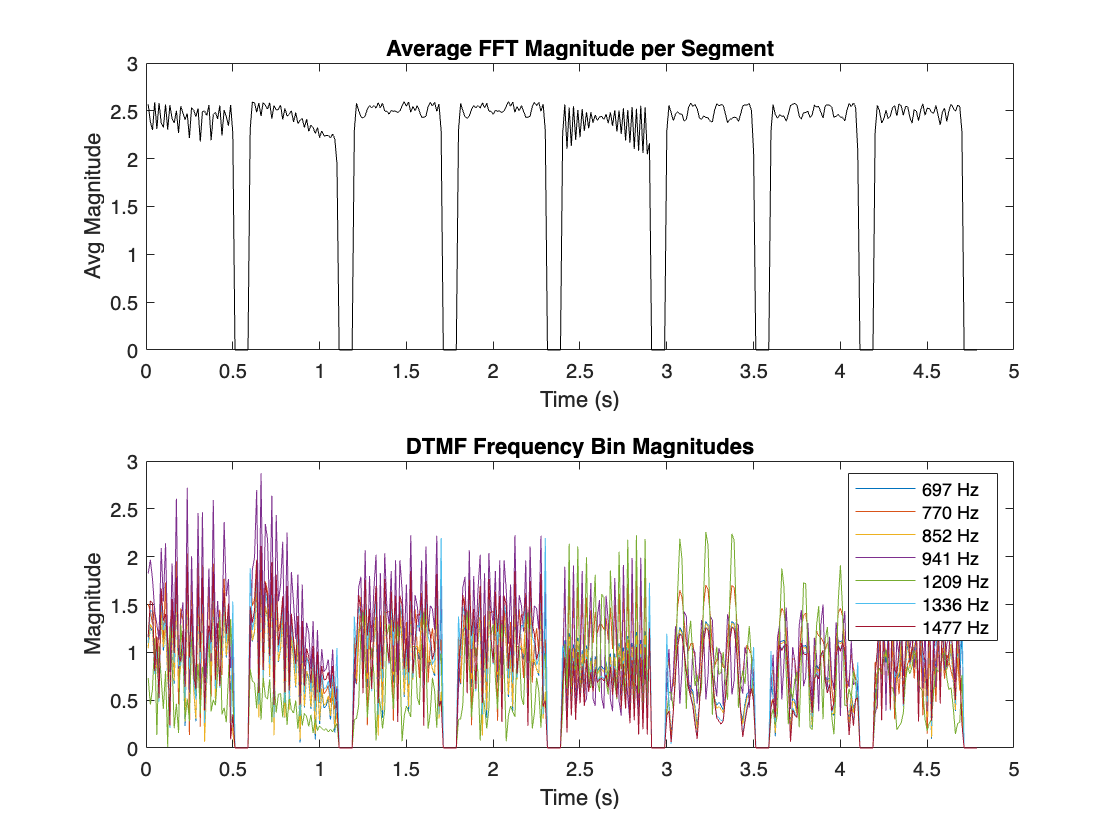

seg_width = 200;
ELEN133L_Lab4_4(x, seg_width);

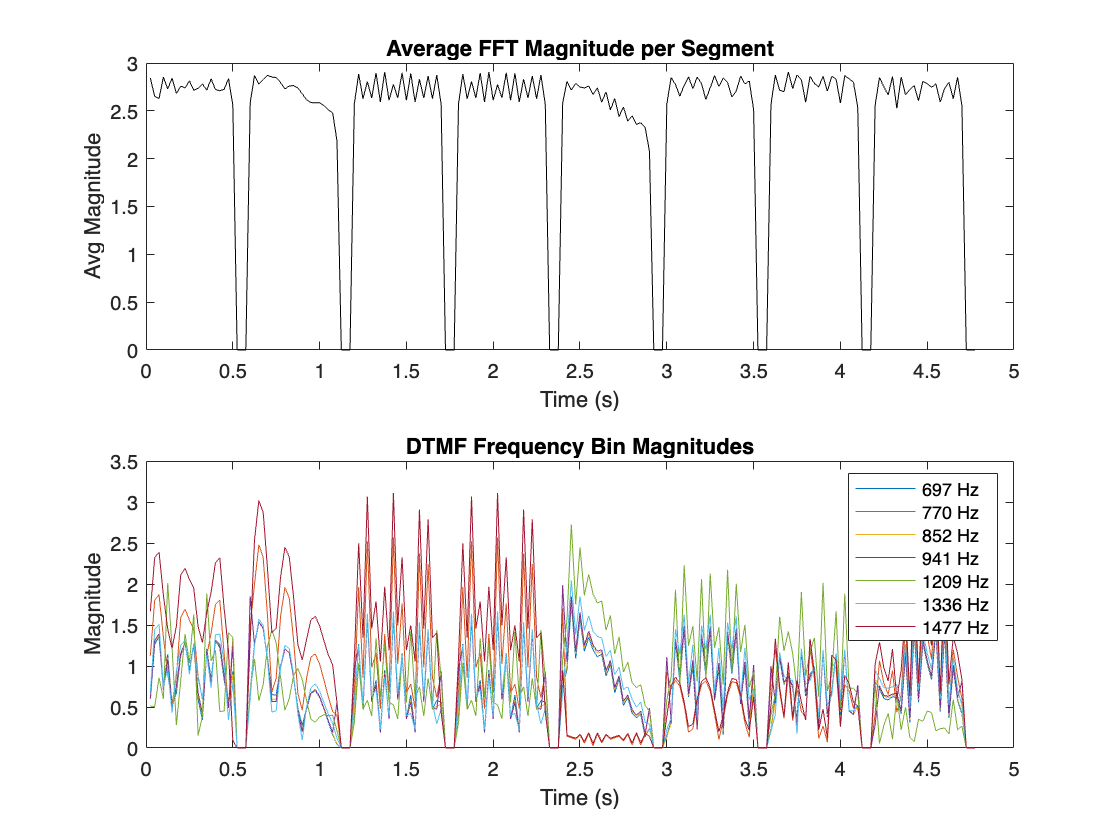

seg_width = 400;
ELEN133L_Lab4_4(x, seg_width);

**Compare these results to the original results for seg_width = 100, 200 and 400, and submit the plot with your report.**

    As you continue to increase seg_width, the row and column frequency plots for the button presses become more and more indistinguishable compared to 

    the original results where you could distinguish the button presses at all values of seg_width used. For all of the plots though, you cannot distinguish what 

    button is pressed despite changing the seg_width.

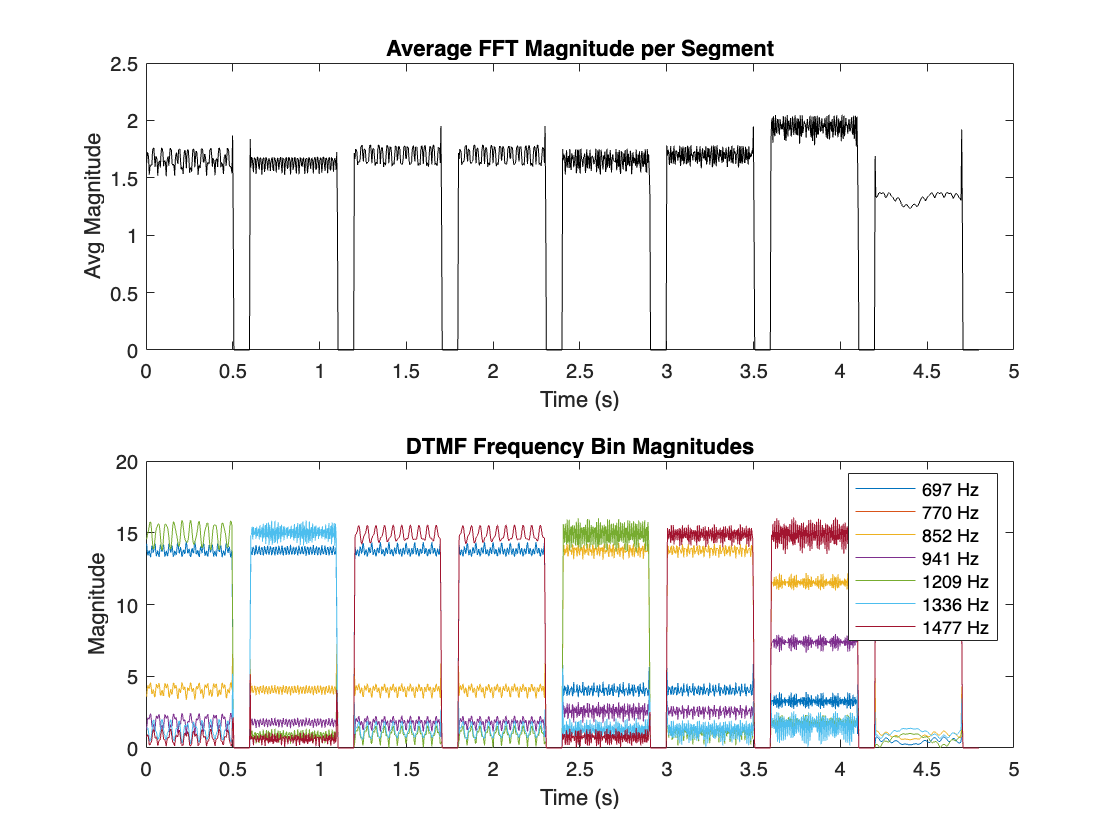

seg_width = 60;
ELEN133L_Lab4_5(x, seg_width);

**Pick a value for seg_width that you think is the smallest value that will work well for determining which buttons was pressed.**

    seg_width = 60

**Pick a value for the number of frequency points computed by fft that improves detection results.**

    1 * seg_width is the number of frequency points conputed by the fft.

## **Step 5**

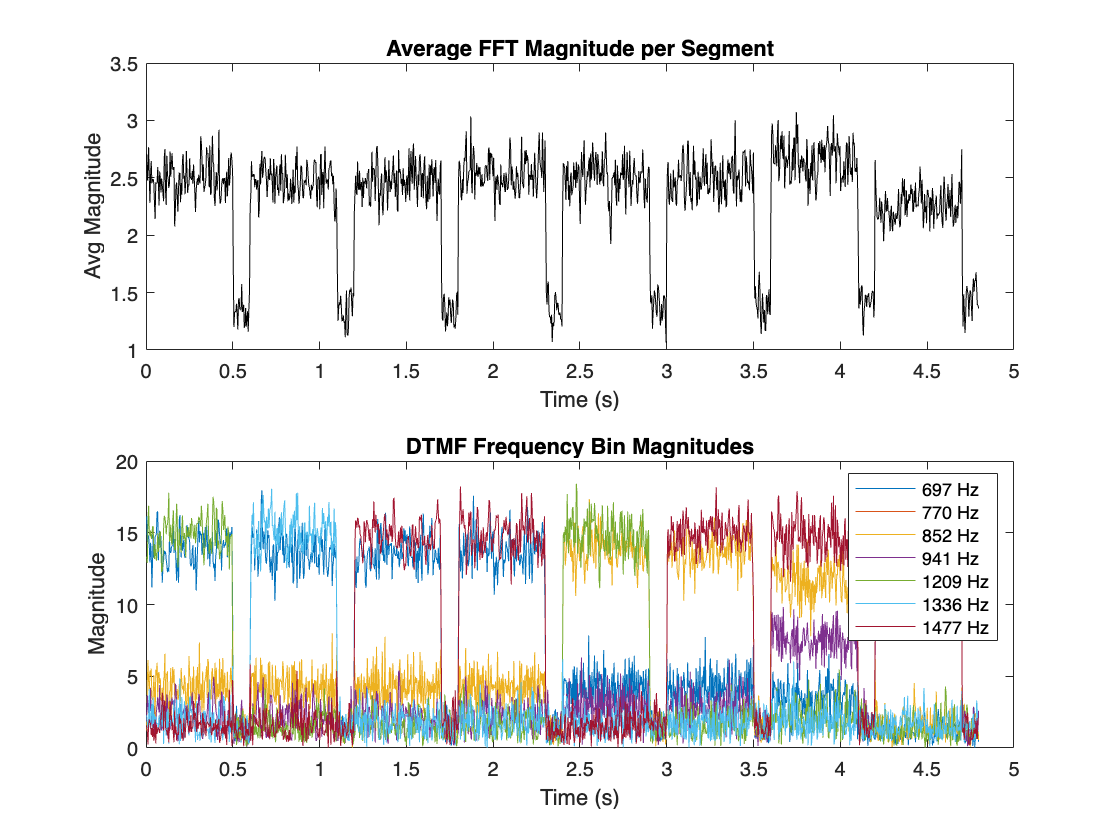

aa = 0.2;
xn = x + aa*randn(1, length(x));
seg_width = 60;
ELEN133L_Lab4_5(xn, seg_width);

**How well do the parameters you chose in Step 4 work on the noisy signals? What improvements would you recommend?**

    The parameters that we chose work well with noise, but when more noise is added it gets harder to tell which buttons were pressed.

    When we add interpolation (2*seg_width), it gets harder to tell what buttons were pressed based on the frequencies present on the plot.

    We would recommend to not interpolate the signal as much as in Step 4, try to get a perfect seg_width value, and maybe use a filter to filter out the noise.